## PART 1: KINEMATICS

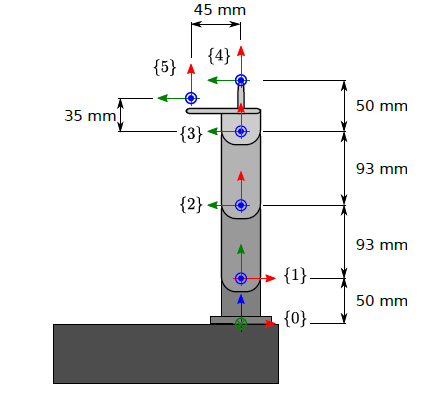

addpath('./src');

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% from DH convention we get:

% {0} -> {1}
T01 = [cos(theta0), 0, sin(theta0), 0;
       sin(theta0), 0, -cos(theta0), 0;
       0, 1, 0, L01;
       0, 0, 0, 1];

% {1} -> {2}
T12 = [cos(theta1), -sin(theta1), 0, L12*cos(theta1);
       sin(theta1), cos(theta1), 0, L12*sin(theta1);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {2} -> {3}
T23 = [cos(theta2), -sin(theta2), 0, L23*cos(theta2);
       sin(theta2), cos(theta2), 0, L23*sin(theta2);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {4}     
T34 = [cos(theta3), -sin(theta3), 0, L34*cos(theta3);
       sin(theta3), cos(theta3), 0, L34*sin(theta3);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {5}
T35 = [1, 0, 0, L35;
       0, 1, 0, L45;
       0, 0, 1, 0;
       0, 0, 0, 1];

% Transformation from {0} to {4}
T04 = simplify(T01*T12*T23*T34)

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{0}\right) & -\sigma_{1}\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(\theta_{0}\right) & -\sigma_{1}\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{2}\\ \sigma_{1} & \sigma_{3} & 0 & 50\,\sigma_{1}+93\,\sin\left(\theta_{1}+\theta_{2}\right)+93\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=50\,\sigma_{3}+93\,\cos\left(\theta_{1}+\theta_{2}\right)+93\,\cos\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$


% Transformation from {0} to {5}
T05 = simplify(T01*T12*T23*T35)

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{1}\\ \cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{1}\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & 93\,\sin\left(\theta_{1}\right)+\sqrt{18409}\,\cos\left(\theta_{1}+\theta_{2}-\mathrm{atan}\left(\frac{128}{45}\right)\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=128\,\cos\left(\theta_{1}+\theta_{2}\right)-45\,\sin\left(\theta_{1}+\theta_{2}\right)+93\,\cos\left(\theta_{1}\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

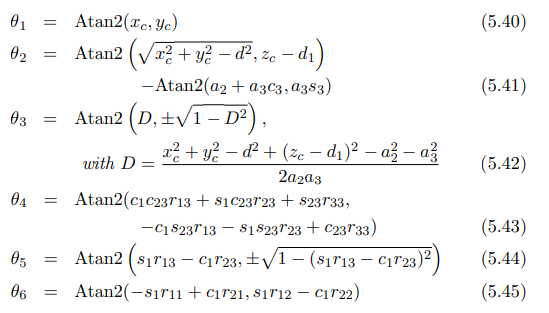

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





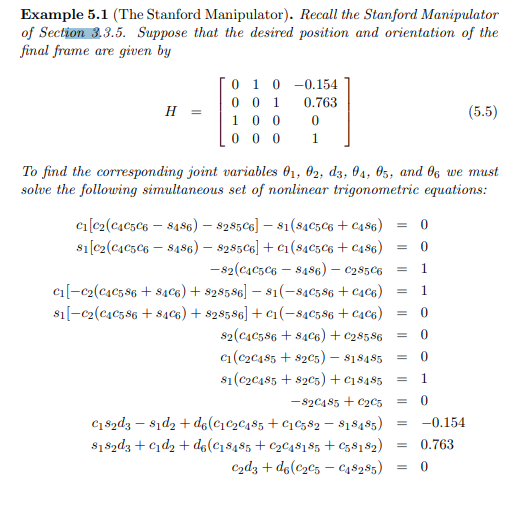

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

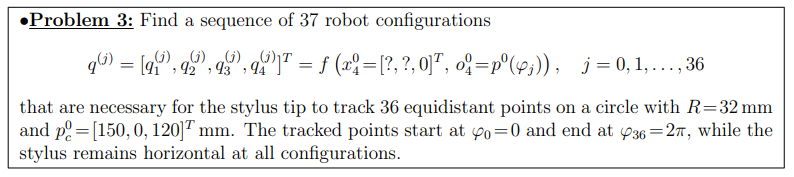

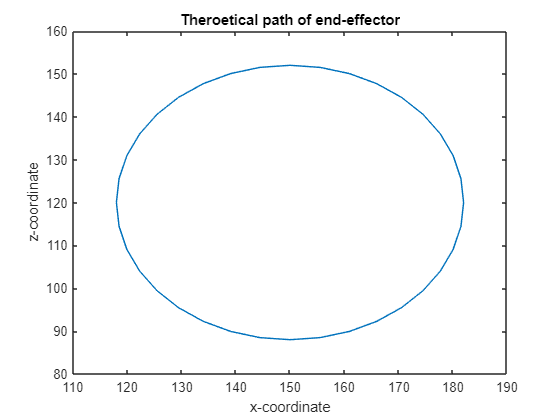


% origin of the circle to be traced
xc = 150;
yc = 0;
zc = 120;

angles = 0:2*pi/36:2*pi; % this is the phi angle reported in the previous line


dx = cos(angles)*32;
dz = sin(angles)*32;

x = xc + dx;
y = yc*ones(1,length(angles));
z = zc + dz;

figure
plot(x,z)
title("Theroetical path of end-effector")
xlabel("x-coordinate")
ylabel("z-coordinate")

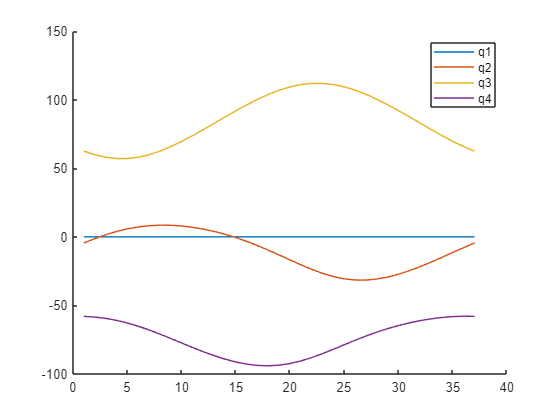



% transform coordinates to angles
% Stylus always parallel to the ground
x04 = [0.97, 0.2, 0];
pos = [x; y; z];

for p = 1:size(pos,2)
    [t1(p),t2(p),t3(p),t4(p)] = invKinematics(x04, pos(:,p));
end

figure
hold on
plot(t1)
plot(t2)
plot(t3)
plot(t4)
legend(["q1","q2","q3","q4"])


pos2 = zeros(4,37);
for i = 1:size(pos,2)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    T04 = T01*T12*T23*T34;
    pos2(:,i) = T04*[0,0,0,1]';
end
pos2

pos2 =   192.0370  191.5801  190.2247  188.0152  185.0246  181.3512  177.1161  172.4584  167.5304  162.4922  157.5052  152.7255  148.2980  144.3506  140.9900  138.2995  136.3393  135.1488  134.7496  135.1488  136.3393  138.2995  140.9900  144.3506  148.2980  152.7255  157.5052  162.4922  167.5304  172.4584  177.1161  181.3512  185.0246  188.0152  190.2247  191.5801  192.0370
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  121.5000  127.0567  132.4446  137.5000  142.0692  146.0134  149.2128  151.5702  153.0138  153.5000  153.0138  151.5702  149.2128  146.0134  142.0692  137.5000  132.4446  127.0567  121.5000  115.9433  110.5554  105.5000  100.9308   96.9866   93.7872 

pos

pos =   182.0000  181.5138  180.0702  177.7128  174.5134  170.5692  166.0000  160.9446  155.5567  150.0000  144.4433  139.0554  134.0000  129.4308  125.4866  122.2872  119.9298  118.4862  118.0000  118.4862  119.9298  122.2872  125.4866  129.4308  134.0000  139.0554  144.4433  150.0000  155.5567  160.9446  166.0000  170.5692  174.5134  177.7128  180.0702  181.5138  182.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  120.0000  125.5567  130.9446  136.0000  140.5692  144.5134  147.7128  150.0702  151.5138  152.0000  151.5138  150.0702  147.7128  144.5134  140.5692  136.0000  130.9446  125.5567  120.0000  114.4433  109.0554  104.0000   99.4308   95.4866   92.2872  

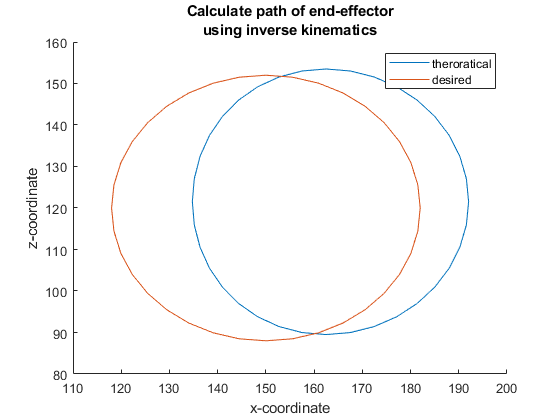


figure
hold on
plot(pos2(1,:),pos2(3,:))
plot(pos(1,:),pos(3,:))
title(["Calculate path of end-effector", "using inverse kinematics"])
xlabel("x-coordinate")
ylabel("z-coordinate")
legend(["theroratical", "desired"])



%t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];

% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 

% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


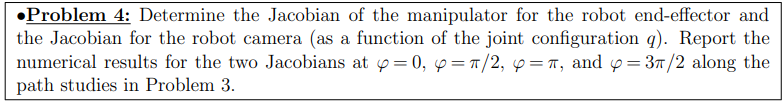



% if you need help figuring out the angles contact Palli


phi = [0 pi/2 pi 3*pi/2];

dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

q1 = ones(1,4);
q2 = ones(1,4);
q3 = ones(1,4);
q4 = ones(1,4);



% Please don't write into t1,t2t3,t4
% using in 6 & 7
%[t1,t2,t3] = theta(x,y,z);
%t4 = ones(1,length(x)).*(pi-t1-t2-t3);



x04 = [0.97, 0.2, 0];
pos = [x; y; z];

for p = 1:size(pos,2)
    [q1(p),q2(p),q3(p),q4(p)] = invKinematics(x04, pos(:,p));
end

for i = 1:length(q1)
   [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));

   % use T35 as the problem statement asks for the camera, not the stylus

   disp("Jacobian stylus")
   disp(phi(i))
   J = Jacob(T01, T12, T23, T34)

   disp("Jacobian camera")
   disp(phi(i))
   J = Jacob(T01, T12, T23, T35)
end

Jacobian stylus


     0



J =    -2.9710  -71.4731  -86.7828         0
  108.3416   -1.9600   -2.3798         0
         0  108.3824   16.6521   50.0000
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


     0



J =    -0.1048  -88.0033 -103.3130  -16.5302
    3.8232   -2.4133   -2.8331   -0.4533
         0    3.8246  -87.9056  -54.5577
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian stylus


    1.5708



J =    -3.2508  -87.4671  -89.7128         0
  118.5448   -2.3986   -2.4601         0
         0  118.5894   25.6165   50.0000
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


    1.5708



J =    -0.4382 -109.4360 -111.6817  -21.9689
   15.9810   -3.0010   -3.0626   -0.6024
         0   15.9870  -76.9858  -52.6023
         0    0.0274    0.0274    0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian stylus


    3.1416



J =     3.5828  -71.4731  -92.4363    0.0000
  130.6509    1.9600    2.5348   -0.0000
         0  130.7001   40.0953   50.0000
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


    3.1416



J =     0.8835 -101.4702 -122.4334  -29.9971
   32.2163    2.7826    3.3574    0.8226
         0   32.2284  -58.3763  -48.4716
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian stylus


    4.7124



J =     3.2508  -55.4791  -91.3605         0
  118.5448    1.5214    2.5053         0
         0  118.5894   32.7956   50.0000
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


Jacobian camera


    4.7124



J =     0.4904  -81.5405 -117.4219  -26.0614
   17.8846    2.2360    3.2200    0.7147
         0   17.8913  -67.9024  -50.6981
         0   -0.0274   -0.0274   -0.0274
         0   -0.9996   -0.9996   -0.9996
    1.0000         0         0         0


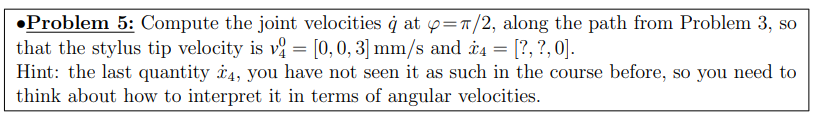

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));
clc
% Parameters to tune
x1 = 0;
x2 = 0;

Vc = [0;0;3;x1;x2;0];

for i = 9
    
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    q = [t1(i),t2(i),t3(i),t4(i)]';
    J = Jacob(T01,T12,T23,T34);

    qA_dot = inv(J'*J)*J'*Vc;


    T04=T01*T12*T23*T34;
    T03=T01*T12*T23;
    T02=T01*T12;
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1/norm(k1);
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2/norm(k2);
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3/norm(k3);
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4/norm(k4);

    w01 = qA_dot(1)*k1;
    w12 = qA_dot(2)*k2;
    w23 = qA_dot(3)*k3;
    w34 = qA_dot(4)*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34;

    % want 0 0 3
    v04 = cross(w04,o4)
    

end

v04 =          0    1.2207         0


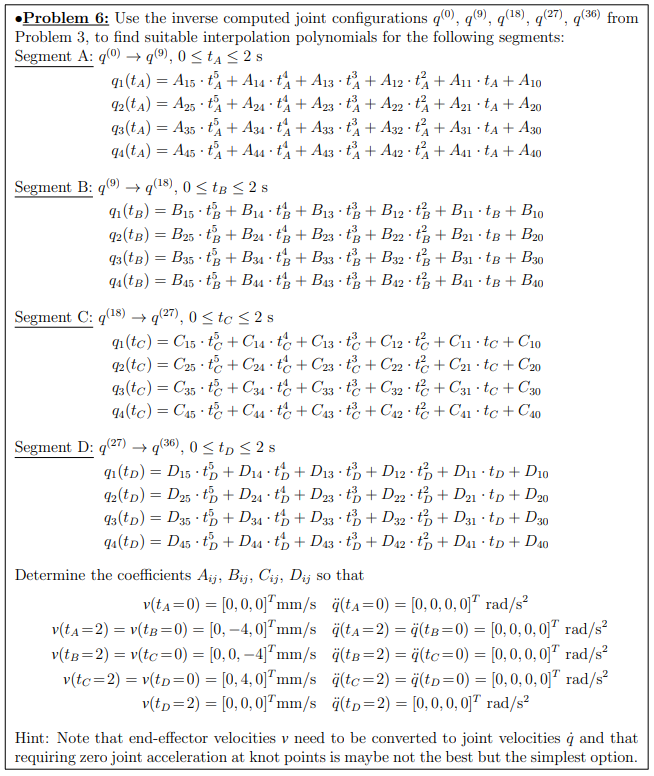

%load("t1.mat");
%load("t2.mat");
%load("t3.mat");
%load("t4.mat");
tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval

V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];

q0 = [t1(1),t2(1),t3(1),t4(1)]';
qA = [t1(10),t2(10),t3(10),t4(10)]';
qB = [t1(19),t2(19),t3(19),t4(19)]';
qC = [t1(28),t2(28),t3(28),t4(28)]';
qD = [t1(37),t2(37),t3(37),t4(37)]';

%vectors of end-effffector velocities v 
[T01,T12,T23,T34,T35] = T_finder(t1(1),t2(1),t3(1),t4(1));
J0 = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(10),t2(10),t3(10),t4(10));
JA = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(19),t2(19),t3(19),t4(19));
JB = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(28),t2(28),t3(28),t4(28));
JC = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(37),t2(37),t3(37),t4(37));
JD = Jacob(T01,T12,T23,T34);


%jaconbian matrix for calculating joint velocities ˙q
q0_dot = [0, 0, 0, 0]';
qA_dot = inv(JA'*JA)*JA'*VA;
qB_dot = inv(JB'*JB)*JB'*VB;
qC_dot = inv(JC'*JC)*JC'*VC;
qD_dot = inv(JD'*JD)*JD'*VD;

%Calculation of joint velocities ˙q
ain = [0,0,0,0]';
aout = [0,0,0,0]';
%acceleration is always 0

A = getConstant(tIN,tOUT,q0,qA,q0_dot,qA_dot,ain,aout)

A =          0   -4.5271   62.4947  -57.9676
   -0.0000         0    0.0000         0
         0         0         0         0
    0.0246   15.5154    8.7086  -24.2241
   -0.0215  -11.6366   -6.5315   18.1680
    0.0046    2.3273    1.3063   -3.6336


B = getConstant(tIN,tOUT,qA,qB,qA_dot,qB_dot,ain,aout)

B =          0    7.8852   69.4616  -77.3468
   -0.0246         0   -0.0000    0.0000
         0         0         0         0
    0.0369  -26.3781   46.6540  -20.2758
   -0.0246   19.7780  -34.9861   15.2081
    0.0046   -3.9550    6.9968   -3.0418


C = getConstant(tIN,tOUT,qB,qC,qB_dot,qC_dot,ain,aout)

C =          0  -13.2532  106.8124  -93.5592
    0.0000   -0.0448    0.0345    0.0103
         0         0         0         0
   -0.0246  -21.8485   -8.2330   30.0815
    0.0215   16.3920    6.1704  -22.5624
   -0.0046   -3.2790   -1.2337    4.5126


D = getConstant(tIN,tOUT,qC,qD,qC_dot,qD_dot,ain,aout)

D =          0  -30.7857  100.2674  -69.4817
    0.0246    0.0000    0.0000   -0.0000
         0         0         0         0
   -0.0369   32.8233  -47.2159   14.3927
    0.0246  -24.6175   35.4120  -10.7945
   -0.0046    4.9235   -7.0824    2.1589



% The constant for Ani is A(n,i) where n is the joint number and i is the
% constant number



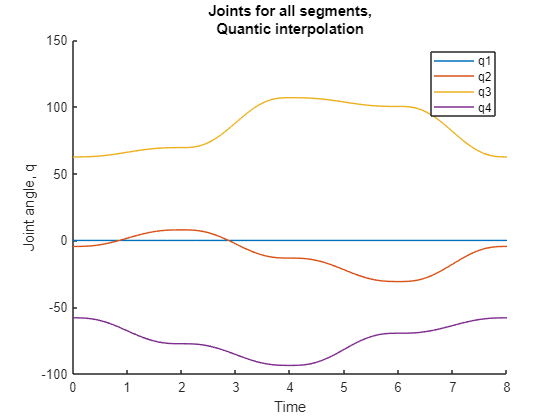

t = 0:0.01:2;
q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3 + A(5,1).*t.^4 + A(6,1).*t.^5;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3 + A(5,2).*t.^4 + A(6,2).*t.^5;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3 + A(5,3).*t.^4 + A(6,3).*t.^5;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3 + A(5,4).*t.^4 + A(6,4).*t.^5;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3 + B(5,1).*t.^4 + B(6,1).*t.^5;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3 + B(5,2).*t.^4 + B(6,2).*t.^5;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3 + B(5,3).*t.^4 + B(6,3).*t.^5;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3 + B(5,4).*t.^4 + B(6,4).*t.^5;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3 + C(5,1).*t.^4 + C(6,1).*t.^5;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3 + C(5,2).*t.^4 + C(6,2).*t.^5;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3 + C(5,3).*t.^4 + C(6,3).*t.^5;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3 + C(5,4).*t.^4 + C(6,4).*t.^5;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3 + D(5,1).*t.^4 + D(6,1).*t.^5;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3 + D(5,2).*t.^4 + D(6,2).*t.^5;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3 + D(5,3).*t.^4 + D(6,3).*t.^5;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3 + D(5,4).*t.^4 + D(6,4).*t.^5;

% combine the joint angles 
q1 = [q1A, q1B(2:end), q1C(2:end), q1D(2:end)];
q2 = [q2A, q2B(2:end), q2C(2:end), q2D(2:end)];
q3 = [q3A, q3B(2:end), q3C(2:end), q3D(2:end)];
q4 = [q4A, q4B(2:end), q4C(2:end), q4D(2:end)];
t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments,","Quantic interpolation"])
legend(["q1","q2","q3","q4"])

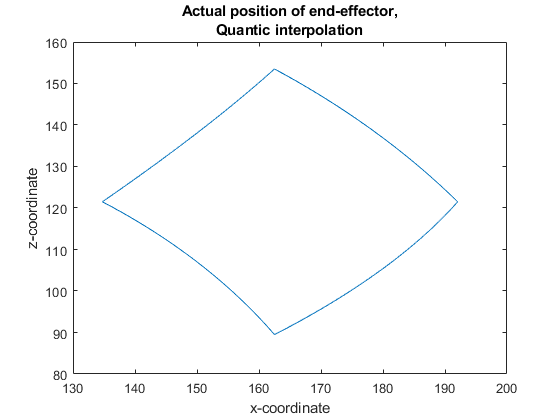



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,","Quantic interpolation"])
xlabel("x-coordinate")
ylabel("z-coordinate")

## Cubic interpolation


A = getConstantCubic(tIN,tOUT,q0,qA,q0_dot,qA_dot,ain,aout)

A =          0   -4.5271   62.4947  -57.9676
         0         0         0         0
    0.0123    9.3093    5.2252  -14.5344
   -0.0062   -3.1031   -1.7417    4.8448


B = getConstantCubic(tIN,tOUT,qA,qB,qA_dot,qB_dot,ain,aout)

B =          0    7.8852   69.4616  -77.3468
   -0.0246         0         0         0
    0.0246  -15.8314   27.9958  -12.1645
   -0.0062    5.2734   -9.3291    4.0557


C = getConstantCubic(tIN,tOUT,qB,qC,qB_dot,qC_dot,ain,aout)

C =          0  -13.2532  106.8124  -93.5592
         0   -0.0448    0.0345    0.0103
   -0.0123  -13.1046   -4.9432   18.0478
    0.0062    4.3719    1.6449   -6.0168


D = getConstantCubic(tIN,tOUT,qC,qD,qC_dot,qD_dot,ain,aout)

D =          0  -30.7857  100.2674  -69.4817
    0.0246         0         0         0
   -0.0246   19.6940  -28.3296    8.6356
    0.0062   -6.5647    9.4432   -2.8785


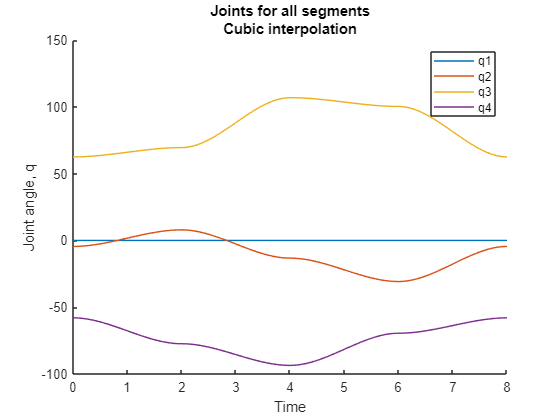

t = 0:0.01:2;
q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3;

% combine the joint angles 
q1 = [q1A, q1B(2:end), q1C(2:end), q1D(2:end)];
q2 = [q2A, q2B(2:end), q2C(2:end), q2D(2:end)];
q3 = [q3A, q3B(2:end), q3C(2:end), q3D(2:end)];
q4 = [q4A, q4B(2:end), q4C(2:end), q4D(2:end)];
t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments","Cubic interpolation"])
legend(["q1","q2","q3","q4"])

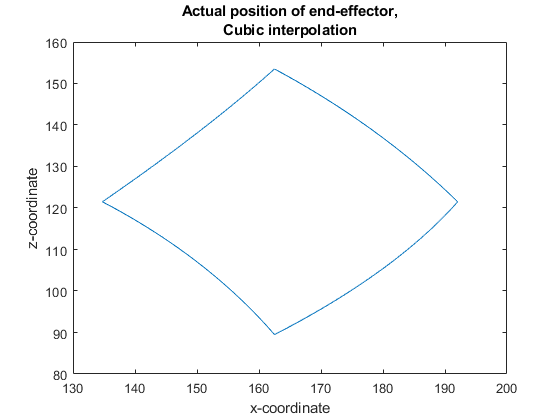



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,", "Cubic interpolation"])
xlabel("x-coordinate")
ylabel("z-coordinate")

## double the knot points

% calculate the approrate speeds at pi/4, 3pi/4 and 5pi/4 and 7pi/4
w = 4*sin(pi/2)/32e-3;
u = 2*pi/37; % angle change at each point
%angles in t are not exactly for pi/4,.....

q0A = [t1(5),t2(5),t3(5),t4(5)]';
q0B = [t1(15),t2(15),t3(15),t4(15)]';
q0C = [t1(23),t2(23),t3(23),t4(23)]';
q0D = [t1(33),t2(33),t3(33),t4(33)]';

V0A = [0;w*sin(u*5)*32e-3;w*cos(u*5)*32e-3;0;0;0];
V0B = [0;w*sin(u*15)*32e-3;w*cos(u*15)*32e-3;0;0;0];
V0C = [0;w*sin(u*23)*32e-3;w*cos(u*23)*32e-3;0;0;0];
V0D = [0;w*sin(u*33)*32e-3;w*cos(u*33)*32e-3;0;0;0];

[T01,T12,T23,T34,T35] = T_finder(t1(5),t2(5),t3(5),t4(5));
J0A = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(15),t2(15),t3(15),t4(15));
J0B = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(23),t2(23),t3(23),t4(23));
J0C = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(33),t2(33),t3(33),t4(33));
J0D = Jacob(T01,T12,T23,T34);

q0A_dot = (J0A'*J0A)\J0A'*V0A;
q0B_dot = (J0B'*J0B)\J0B'*V0B;
q0C_dot = (J0C'*J0C)\J0C'*V0C;
q0D_dot = (J0D'*J0D)\J0D'*V0D;


A0 = getConstant(tIN,tOUT,q0,q0A,q0_dot,q0A_dot,ain,aout)

A0 =          0   -4.5271   62.4947  -57.9676
         0   -0.0000         0    0.0000
         0         0         0         0
   -0.0162   12.8383   -6.7816   -6.0567
    0.0142   -9.6249    5.0820    4.5430
   -0.0030    1.9246   -1.0160   -0.9086


A = getConstant(tIN,tOUT,q0A,qA,q0A_dot,qA_dot,ain,aout)

A =          0    5.7676   57.0426  -62.8102
    0.0162    0.0301   -0.0335    0.0034
         0         0         0         0
    0.0003    2.6019   15.5740  -18.1759
   -0.0053   -1.9552  -11.6763   13.6315
    0.0016    0.3914    2.3348   -2.7263


B0 = getConstant(tIN,tOUT,qA,q0B,qA_dot,q0B_dot,ain,aout)

B0 =          0    7.8852   69.4616  -77.3468
   -0.0246   -0.0000   -0.0000   -0.0000
         0         0         0         0
    0.0210  -10.5211   27.8825  -17.3614
   -0.0107    7.8863  -20.9075   13.0211
    0.0016   -1.5768    4.1810   -2.6042


B = getConstant(tIN,tOUT,q0B,qB,q0B_dot,qB_dot,ain,aout)

B =          0   -0.5601   91.7958  -91.2357
    0.0159   -0.0356    0.0353    0.0003
         0         0         0         0
   -0.0238  -15.7680   18.6832   -2.9153
    0.0159   11.8248  -14.0125    2.1877
   -0.0030   -2.3648    2.8025   -0.4377


C0 = getConstant(tIN,tOUT,qB,q0C,qB_dot,q0C_dot,ain,aout)

C0 =          0  -13.2532  106.8124  -93.5592
         0   -0.0448    0.0345    0.0103
         0         0         0         0
    0.0196  -16.6632    6.1686   10.4946
   -0.0172   12.4988   -4.6285   -7.8703
    0.0037   -2.4999    0.9259    1.5740


C = getConstant(tIN,tOUT,q0C,qC,q0C_dot,qC_dot,ain,aout)

C =          0  -26.6642  111.8034  -85.1392
   -0.0196   -0.0333    0.0183    0.0150
         0         0         0         0
    0.0048   -5.1020  -14.4474   19.5494
    0.0019    3.8306   10.8333  -14.6639
   -0.0009   -0.7665   -2.1664    2.9330


D0 = getConstant(tIN,tOUT,qC,q0D,qC_dot,q0D_dot,ain,aout)

D0 =          0  -30.7857  100.2674  -69.4817
    0.0246    0.0000    0.0000   -0.0000
         0         0         0         0
   -0.0233   15.3898  -27.5242   12.1344
    0.0127  -11.5387   20.6408   -9.1021
   -0.0021    2.3074   -4.1279    1.8206


D = getConstant(tIN,tOUT,q0D,qD,q0D_dot,qD_dot,ain,aout)

D =          0  -18.4503   78.2331  -59.7829
   -0.0136    0.0295   -0.0187   -0.0108
         0         0         0         0
    0.0204   17.3596  -19.6450    2.2853
   -0.0136  -13.0234   14.7361   -1.7127
    0.0025    2.6051   -2.9474    0.3424



t = 0:0.01:1;
q10A = A0(1,1) + A0(2,1).*t + A0(3,1).*t.^2 + A0(4,1).*t.^3 + A0(5,1).*t.^4 + A0(6,1).*t.^5;
q20A = A0(1,2) + A0(2,2).*t + A0(3,2).*t.^2 + A0(4,2).*t.^3 + A0(5,2).*t.^4 + A0(6,2).*t.^5;
q30A = A0(1,3) + A0(2,3).*t + A0(3,3).*t.^2 + A0(4,3).*t.^3 + A0(5,3).*t.^4 + A0(6,3).*t.^5;
q40A = A0(1,4) + A0(2,4).*t + A0(3,4).*t.^2 + A0(4,4).*t.^3 + A0(5,4).*t.^4 + A0(6,4).*t.^5;

q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3 + A(5,1).*t.^4 + A(6,1).*t.^5;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3 + A(5,2).*t.^4 + A(6,2).*t.^5;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3 + A(5,3).*t.^4 + A(6,3).*t.^5;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3 + A(5,4).*t.^4 + A(6,4).*t.^5;

q10B = B0(1,1) + B0(2,1).*t + B0(3,1).*t.^2 + B0(4,1).*t.^3 + B0(5,1).*t.^4 + B0(6,1).*t.^5;
q20B = B0(1,2) + B0(2,2).*t + B0(3,2).*t.^2 + B0(4,2).*t.^3 + B0(5,2).*t.^4 + B0(6,2).*t.^5;
q30B = B0(1,3) + B0(2,3).*t + B0(3,3).*t.^2 + B0(4,3).*t.^3 + B0(5,3).*t.^4 + B0(6,3).*t.^5;
q40B = B0(1,4) + B0(2,4).*t + B0(3,4).*t.^2 + B0(4,4).*t.^3 + B0(5,4).*t.^4 + B0(6,4).*t.^5;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3 + B(5,1).*t.^4 + B(6,1).*t.^5;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3 + B(5,2).*t.^4 + B(6,2).*t.^5;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3 + B(5,3).*t.^4 + B(6,3).*t.^5;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3 + B(5,4).*t.^4 + B(6,4).*t.^5;

q10C = C0(1,1) + C0(2,1).*t + C0(3,1).*t.^2 + C0(4,1).*t.^3 + C0(5,1).*t.^4 + C0(6,1).*t.^5;
q20C = C0(1,2) + C0(2,2).*t + C0(3,2).*t.^2 + C0(4,2).*t.^3 + C0(5,2).*t.^4 + C0(6,2).*t.^5;
q30C = C0(1,3) + C0(2,3).*t + C0(3,3).*t.^2 + C0(4,3).*t.^3 + C0(5,3).*t.^4 + C0(6,3).*t.^5;
q40C = C0(1,4) + C0(2,4).*t + C0(3,4).*t.^2 + C0(4,4).*t.^3 + C0(5,4).*t.^4 + C0(6,4).*t.^5;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3 + C(5,1).*t.^4 + C(6,1).*t.^5;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3 + C(5,2).*t.^4 + C(6,2).*t.^5;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3 + C(5,3).*t.^4 + C(6,3).*t.^5;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3 + C(5,4).*t.^4 + C(6,4).*t.^5;

q10D = D0(1,1) + D0(2,1).*t + D0(3,1).*t.^2 + D0(4,1).*t.^3 + D0(5,1).*t.^4 + D0(6,1).*t.^5;
q20D = D0(1,2) + D0(2,2).*t + D0(3,2).*t.^2 + D0(4,2).*t.^3 + D0(5,2).*t.^4 + D0(6,2).*t.^5;
q30D = D0(1,3) + D0(2,3).*t + D0(3,3).*t.^2 + D0(4,3).*t.^3 + D0(5,3).*t.^4 + D0(6,3).*t.^5;
q40D = D0(1,4) + D0(2,4).*t + D0(3,4).*t.^2 + D0(4,4).*t.^3 + D0(5,4).*t.^4 + D0(6,4).*t.^5;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3 + D(5,1).*t.^4 + D(6,1).*t.^5;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3 + D(5,2).*t.^4 + D(6,2).*t.^5;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3 + D(5,3).*t.^4 + D(6,3).*t.^5;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3 + D(5,4).*t.^4 + D(6,4).*t.^5;

q1 = [q10A, q1A(2:end), q10B(2:end), q1B(2:end), q10C(2:end), q1C(2:end), q10D(2:end), q1D(2:end)];
q2 = [q20A, q2A(2:end), q20B(2:end), q2B(2:end), q20C(2:end), q2C(2:end), q20D(2:end), q2D(2:end)];
q3 = [q30A, q3A(2:end), q30B(2:end), q3B(2:end), q30C(2:end), q3C(2:end), q30D(2:end), q3D(2:end)];
q30A(end)

ans = 59.7791

q3A(1)

ans = 57.0426

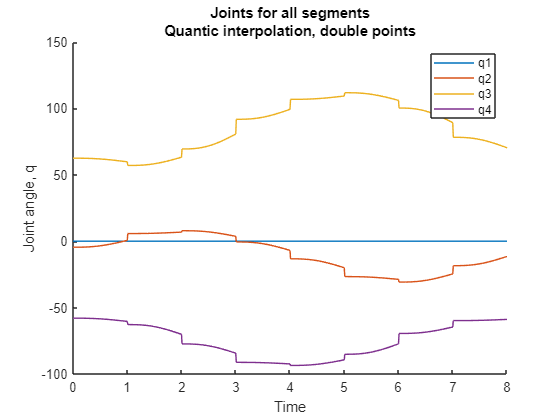

q4 = [q40A, q4A(2:end), q40B(2:end), q4B(2:end), q40C(2:end), q4C(2:end), q40D(2:end), q4D(2:end)];

t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments","Quantic interpolation, double points"])
legend(["q1","q2","q3","q4"])

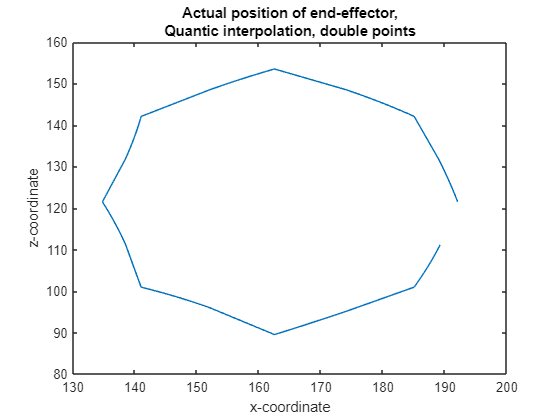



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,", "Quantic interpolation, double points"])
xlabel("x-coordinate")
ylabel("z-coordinate")

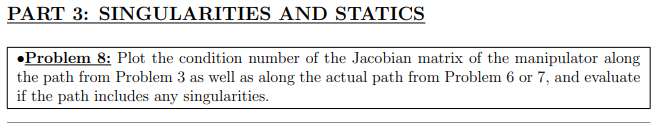

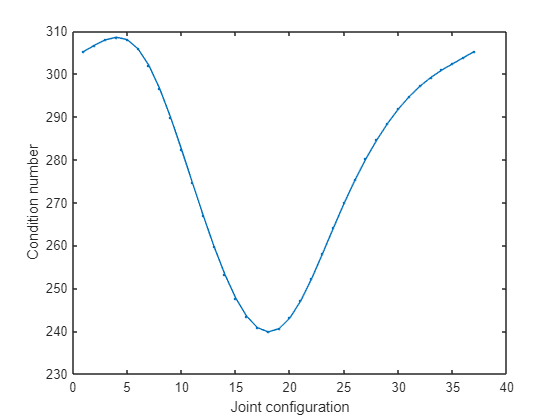


k=zeros(1,length(t1));
for i = 1:length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34); % Get jacobian at a given point
    k(i) = norm((J'*J)\J')*norm(J); % calculate the condition number
end
figure;
plot(k,'.-')
xlabel('Joint configuration')
ylabel('Condition number')

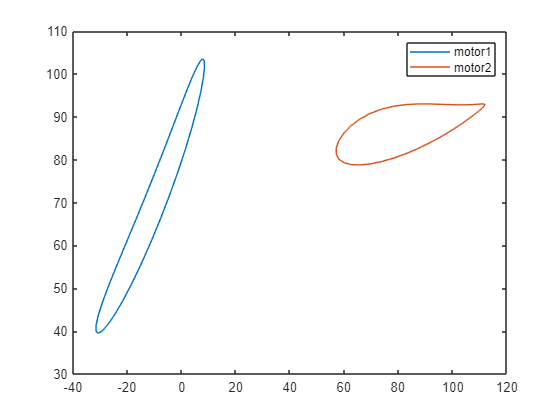

% this uses the collection of angles from problem 3
len = length(t1);
torque2 = zeros(1,len);
torque3 = zeros(1,len);
torque4 = zeros(1,len);

L12 = 93;
L23 = 93;
L34 = 50;
F = 1;

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i),1);



end

figure
plot(t2,torque2)
hold on

plot(t3,torque3)

%plot(t4,torque4)

legend(["motor1", "motor2"])%,"motor3"])


disp("Motor 4 is omitted here as the torques are smaller than")

Motor 4 is omitted here as the torques are smaller than